Ve skriptu "BDG_detail" jsme se seznámili s metodou největšího spádu. Následně jsme ve skriptu "BDG_sinus" narazili na problém, pokud účelová funkce obsahuje více lokálních minim. V tomto skriptu se dozvíme jak se s touto situací vypořádat

Narozdíl od skriptu "BDG_sinus" si zde nagenerujeme data pomocí funkce. V tomto případě se jedná o fnunkci:

#### 
$$y_{\left(x\right)} =\cos \left(2\left(x-1\right)+3\right)$$
 

func = @(x) cos((x-1).*2+3); % funkce pro nagenerování dat                
from = -pi;                  % rozsah pro od ...
to = pi;                     % do pro nagenerování dat
N = 20;                         % počet vzorků
x = from:((to-from)/(N-1)):to;  % vzorkovací čas            
y = awgn(func(x),20);           % generátor naměřených dat skrze funkci pro nagenerování dat (prostě přidá do funkce šum)    

Klasicky navolíme maximální chybu výpočtu a koeficinet učení.

alpha = 0.001;      % míra učení
tau = 0.01;         % maximální možná chyba pro ukončení výpočtu
syms q_sym;

Zde je vytvořena bázová funkce. Ta má tvar:

#### 
$$y_{\left(x\right)} =\cos \left(\textrm{qx}+\frac{q}{2}\right)$$


Tato bázová funkce nikdy úplně kvalitně neaproximuje nagenerovaná data, ale vytvoří nám "pěknou" ztrátovou funkci pro vysvětlení momentu.

y_a = cos(q_sym.*x)+0.5.*q_sym; % zde je provedno vytvořrní bázové funkce

Následně je vytvořena ztrátová funkce pomocí metody nejmenších čtverců:

E_sym = sum((y - y_a).^2);

A ta je poté derivována podle parametru $q$.

dE_sym = diff(E_sym,q_sym);

"Náhodný" výchozí bod je zde zvolen -3.

q = -3;

A nyní už samotný výpočet. Na první pohled je naprosto stejný jako klasický BGD, ale udělám zde maličkost navíc. V každé iteraci si uložím velikost gradientu(derivace), kterou jsem spočítal v iteraci minulé. Důvod proč to dělám je ten, že výpočet následujícího kroku je závislý jak na výpočtu současně spočteného gradientu, tak na gradientu, který jsem spočetl v předchozí iteraci. To lze vidět níže, kde si nejprve zachovám gradient spočtený v předešlé iteraci, následně vypočtu gradient nový klasickým způsobem a poté nový gradient upravím podle vzorečku:

####  
$$v_{\left(t\right)} ={\gamma v}_{\left(t-1\right)} +\alpha \frac{\textrm{dE}}{\textrm{dq}}$$


kde $\alpha$ je klasicky koeficient učení, a $\frac{\textrm{dE}}{\textrm{dq}}$ je derivace ztrátové funkce podle koeficientu $q$. Co je zde navíc oproti klasickému BGD je člen ${\gamma v}_{\left(t-1\right)}$, kde $v_{\left(t-1\right)}$ je upravený gradient vypočtený v minulé iteraci a $\gamma$je koeficient toho, jak moc se tento starý gradient promítne do nově vypočteného gradientu. Pokud bude $\gamma$rovno nule, tak se nebude projevovat nijak, pokud bude rovno jedné, tak bude mít stejnou váhu, jako gradient nový.  

dE = 0;
sigma = 0.99;
for i = 1:1000 
    
    dE_old = dE; % Zde dochází k uložení vypočteného gradientu z předchozí iterace
    dE = (double(subs(dE_sym,q_sym,q))); % Nyní probíhá klasické spočtení nového gradientu
    dE = ((dE_old/5)+dE); % A zde dochází k upravení nového gradientu na základě starého (zde v podobě přičtení pětiny starého)
    
%     Tohle je taková moje úprava, která vlastně zvýrazní vysoké derivace. To zanemná, že pokud je "hybnost" nabraná z předchozích výpočtů velká, tak se ještě zvětší, ale pokud je naopak malá (< 1), tak se naopak utlumí. Je to věc která mi docela hezky fungovala, tak jsem si zde nechal.        
% 
%     if(dE >= 0)
%         dE = abs(dE)^(1.3);
%     else
%         dE = -(abs(dE)^(1.3));    
%     end
    
    if abs(dE) < tau
        break;
    end
    
    q = (q*sigma) - (dE*alpha)
end

q = -2.9098

q = -2.8035

q = -2.6937

q = -2.5884

q = -2.4934

q = -2.4111

q = -2.3411

q = -2.2814

q = -2.2299

q = -2.1847

q = -2.1445

q = -2.1082

q = -2.0750

q = -2.0446

q = -2.0164

q = -1.9902

q = -1.9658

q = -1.9429

q = -1.9215

q = -1.9014

q = -1.8825

q = -1.8648

q = -1.8482

q = -1.8325

q = -1.8178

q = -1.8040

q = -1.7910

q = -1.7787

q = -1.7672

q = -1.7563

q = -1.7461

q = -1.7364

q = -1.7272

q = -1.7186

q = -1.7104

q = -1.7026

q = -1.6952

q = -1.6882

q = -1.6815

q = -1.6752

q = -1.6691

q = -1.6633

q = -1.6578

q = -1.6525

q = -1.6474

q = -1.6425

q = -1.6378

q = -1.6333

q = -1.6290

q = -1.6248

q = -1.6208

q = -1.6169

q = -1.6131

q = -1.6095

q = -1.6059

q = -1.6025

q = -1.5992

q = -1.5959

q = -1.5928

q = -1.5897

q = -1.5867

q = -1.5837

q = -1.5809

q = -1.5781

q = -1.5753

q = -1.5726

q = -1.5700

q = -1.5674

q = -1.5648

q = -1.5623

q = -1.5598

q = -1.5574

q = -1.5550

q = -1.5526

q = -1.5502

q = -1.5479

q = -1.5456

q = -1.5433

q = -1.5410

q = -1.5388

q = -1.5365

q = -1.5343

q = -1.5321

q = -1.5299

q = -1.5277

q = -1.5255

q = -1.5233

q = -1.5211

q = -1.5189

q = -1.5167

q = -1.5144

q = -1.5122

q = -1.5100

q = -1.5077

q = -1.5055

q = -1.5032

q = -1.5009

q = -1.4986

q = -1.4962

q = -1.4939

q = -1.4915

q = -1.4890

q = -1.4866

q = -1.4841

q = -1.4815

q = -1.4789

q = -1.4763

q = -1.4736

q = -1.4708

q = -1.4680

q = -1.4651

q = -1.4621

q = -1.4591

q = -1.4560

q = -1.4527

q = -1.4494

q = -1.4460

q = -1.4425

q = -1.4388

q = -1.4350

q = -1.4311

q = -1.4270

q = -1.4227

q = -1.4182

q = -1.4135

q = -1.4086

q = -1.4035

q = -1.3980

q = -1.3923

q = -1.3863

q = -1.3798

q = -1.3730

q = -1.3657

q = -1.3579

q = -1.3496

q = -1.3406

q = -1.3309

q = -1.3204

q = -1.3090

q = -1.2965

q = -1.2829

q = -1.2679

q = -1.2513

q = -1.2330

q = -1.2126

q = -1.1898

q = -1.1644

q = -1.1359

q = -1.1041

q = -1.0686

q = -1.0293

q = -0.9863

q = -0.9401

q = -0.8917

q = -0.8427

q = -0.7950

q = -0.7506

q = -0.7111

q = -0.6773

q = -0.6493

q = -0.6269

q = -0.6091

q = -0.5953

q = -0.5847

q = -0.5765

q = -0.5703

q = -0.5655

q = -0.5619

q = -0.5591

q = -0.5570

q = -0.5554

q = -0.5542

q = -0.5532

q = -0.5525

q = -0.5520

q = -0.5516

q = -0.5512

q = -0.5510

q = -0.5508

q = -0.5507

q = -0.5506

q = -0.5505

q = -0.5504

q = -0.5504

q = -0.5503

q = -0.5503

q = -0.5503

q = -0.5503

q = -0.5503

q = -0.5503

q = -0.5503

q = -0.5503

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

q = -0.5502

Zbytek výpočtu už byl klasický. Za znímu ještě stojí koeficient sigma, kterým lze nastavit "tlumení". 

Následuje vypsání vypočtených koeficientů:

q

q = -0.5502

Vykreslení naměřených dat.

plot(x,y,"ro");
hold on;

Vykreslení aproximace vypočteným modelem.

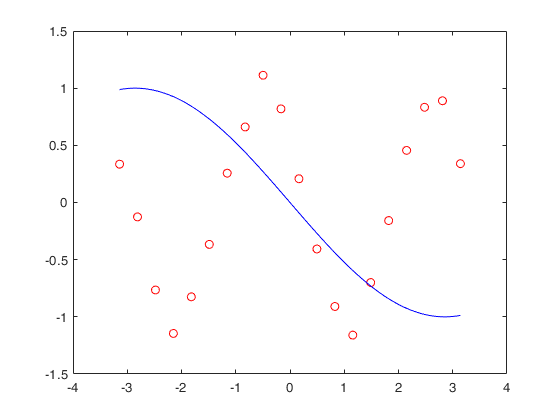

plot(from:((to-from)/(N*10-1)):to,sin((from:((to-from)/(N*10-1)):to).*q),"b-");
hold off;

Vykreslení ztrátové funkce. A tady právě vidíme tu výhodu ve využití momentu. Jelikož náš výchozí koeficient měl hodnotu -3, tak jsme se vlastně nacházeli v levé části grafu. Klasický BGD by prostě našel lokální minimum s hodnotou koeficientu -2 a dál by neřešil. Ale díky momentu, vlastně metoda nabrala takovou rychlost, že lokální minimum překonala a dojela až do druhého minima, které už je ale globální ($q=-0,5$). Takže metoda našla globální minimum a všichni jsme z toho šťastný.

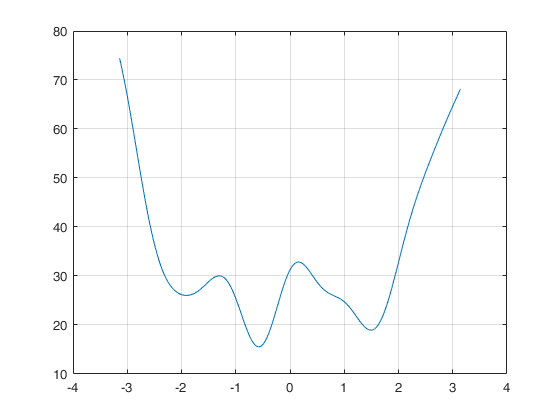

plot(from:((to-from)/(N*10-1)):to,double(subs(E_sym,q_sym,from:((to-from)/(N*10-1)):to)));
grid on;

Vykreslení derivace ztrátové funkce.

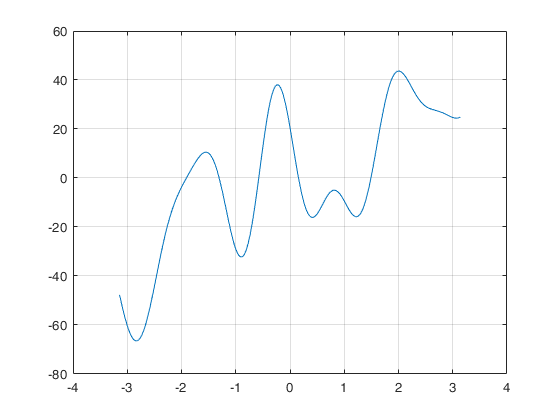

plot(from:((to-from)/(N*10-1)):to,double(subs(dE_sym,q_sym,from:((to-from)/(N*10-1)):to)));
grid on;

Co kdybychom chtěli tuto metodu ještě vylepšit? Tak proč neudělat moment adaptivní? → skript "BGD_ADAM".